#### Test Case 1: 13 Cambridge Communities - Trapezoidal (Flip Theta)

clc; clear; close all;

t_start = 0;
t_stop = 100;
timestep = 0.05;

rng(5);
[P, x_start, p, u] = initializeCambridgeCommunities();

% test FE function
tic;
[X, trapFlipThetaNewtonLastIter] = trapezoidalFlipTheta(P, x_start, p, u, t_stop, timestep);   %t_start is always 0

Step = 10/2000
Step = 20/2000
Step = 30/2000
Step = 40/2000
Step = 50/2000
Step = 60/2000
Step = 70/2000
Step = 80/2000
Step = 90/2000
Step = 100/2000
Step = 110/2000
Step = 120/2000
Step = 130/2000
Step = 140/2000
Step = 150/2000
Step = 160/2000
Step = 170/2000
Step = 180/2000
Step = 190/2000
Step = 200/2000
Step = 210/2000
Step = 220/2000
Step = 230/2000
Step = 240/2000
Step = 250/2000
Step = 260/2000
Step = 270/2000
Step = 280/2000
Step = 290/2000
Step = 300/2000
Step = 310/2000
Step = 320/2000
Step = 330/2000
Step = 340/2000
Step = 350/2000
Step = 360/2000
Step = 370/2000
Step = 380/2000
Step = 390/2000
Step = 400/2000
Step = 410/2000
Step = 420/2000
Step = 430/2000
Step = 440/2000
Step = 450/2000
Step = 460/2000
Step = 470/2000
Step = 480/2000
Step = 490/2000
Step = 500/2000
Step = 510/2000
Step = 520/2000
Step = 530/2000
Step = 540/2000
Step = 550/2000
Step = 560/2000
Step = 570/2000
Step = 580/2000
Step = 590/2000
Step = 600/2000
Step = 610/2000
Step = 620/2000
Step = 630/2000
S

trapFlipThetaElapsedTime = toc;

%% Convert SEIR cell time series to matrix
for i = 1:size(X,2)
    
    trapFlipThetaState(:,i) = convertSeirCellToMat(X(:,i));
    
end

save('techChallengeFlipThetaStats.mat', 'trapFlipThetaState', '-append');
save('techChallengeFlipThetaStats.mat', 'trapFlipThetaElapsedTime', '-append');
save('techChallengeFlipThetaStats.mat', 'trapFlipThetaNewtonLastIter', '-append');

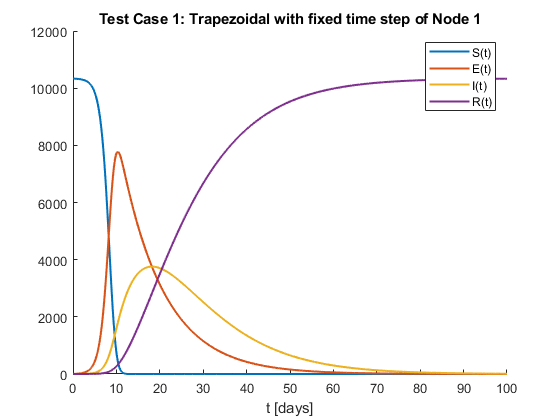

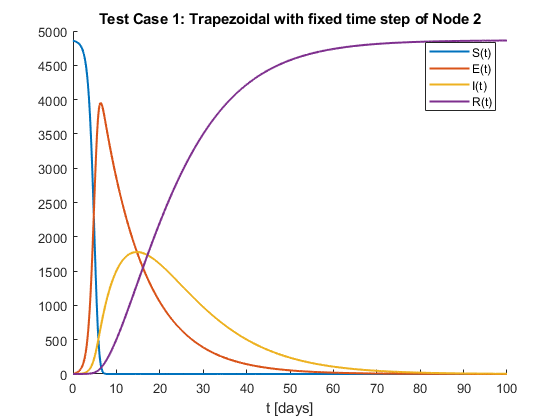

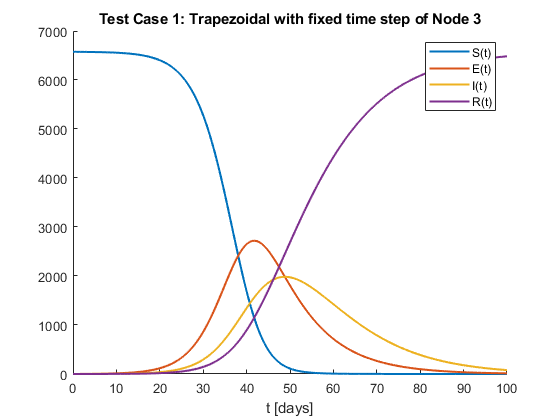

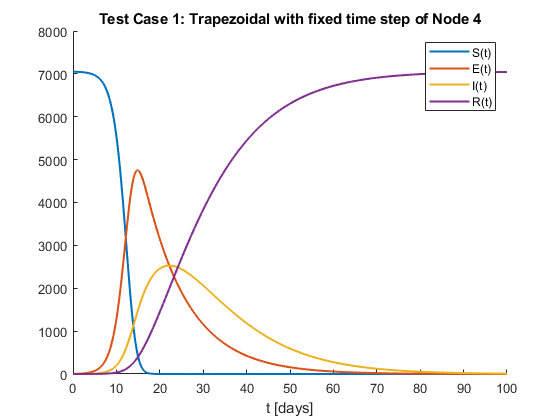

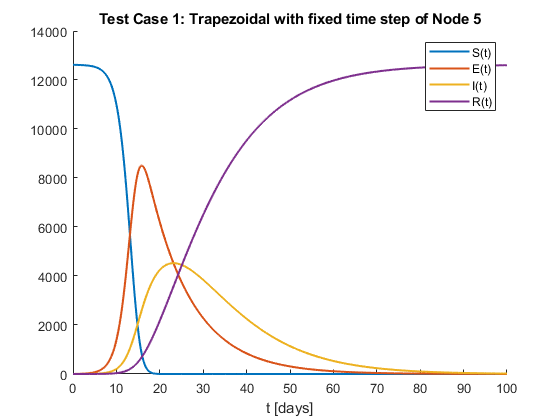

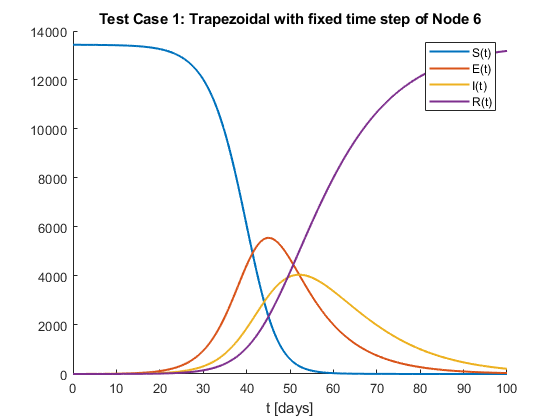

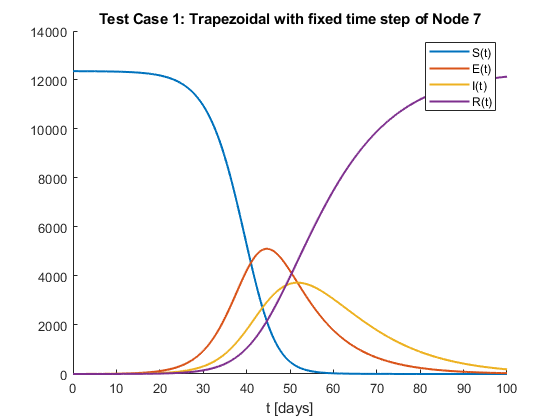

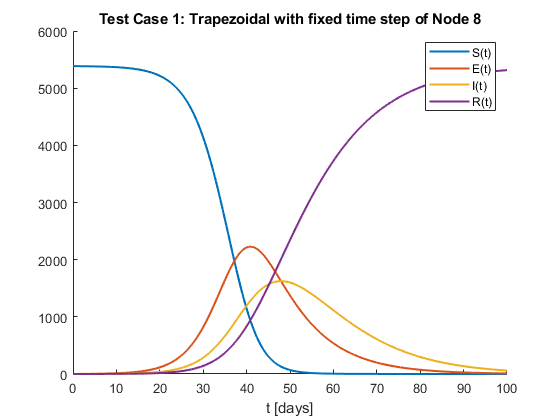

clc; clear; close all;

t_start = 0;
t_stop = 100;

load('techChallengeFlipThetaStats.mat');

%% Convert SEIR matrix time series to cell
for i = 1:size(trapFlipThetaState,2)
    
    X(:,i) = convertSeirMatToCell(trapFlipThetaState(:,i));
    
end

%% Plot SEIR curves for each node
for i = 1:size(X,1)
    
    State = X(i,:);
    state = [State{1:end}];
    
    N(i,:) = sum(state, 1);
    
    figure(i);
    hold on;
    days = linspace(t_start,t_stop,length(state(1,1:end)));
    plot(days, state(1,1:end),  'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, state(2,1:end),  'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, state(3,1:end), 'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, state(4,1:end), 'LineWidth', 1.5);
    xlabel('t [days]');
    hold off;
    legend('S(t)','E(t)','I(t)','R(t)');
    title(['Test Case 1: Trapezoidal with fixed time step of' ' Node ', num2str(i)])
    
    if i == 1
        sumState = state;     
    else
        sumState = sumState + state;     
    end
end

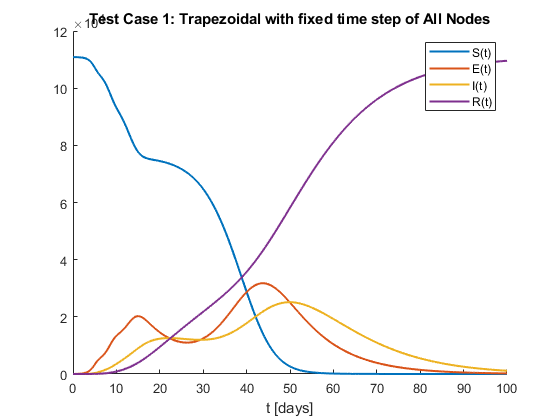


figure;
hold on;
days = linspace(t_start,t_stop,length(sumState(1,1:end)));
plot(days, sumState(1,1:end),  'LineWidth', 1.5);
xlabel('t [days]');

plot(days, sumState(2,1:end),  'LineWidth', 1.5);
xlabel('t [days]');

plot(days, sumState(3,1:end), 'LineWidth', 1.5);
xlabel('t [days]');

plot(days, sumState(4,1:end), 'LineWidth', 1.5);
xlabel('t [days]');
hold off;
legend('S(t)','E(t)','I(t)','R(t)');
title('Test Case 1: Trapezoidal with fixed time step of All Nodes')

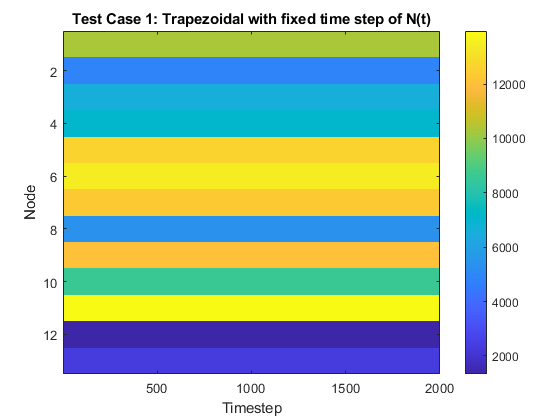


figure;
imagesc(N(:,:));
title('Test Case 1: Trapezoidal with fixed time step of N(t)');
xlabel('Timestep');
ylabel('Node');
colorbar;

#### Test Case 2: 13 Cambridge Communities - Forward Euler (Flip Theta)

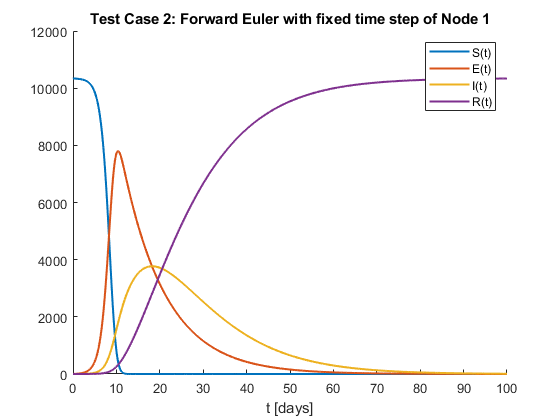

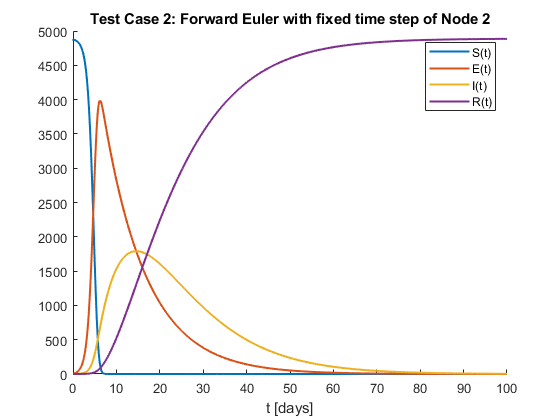

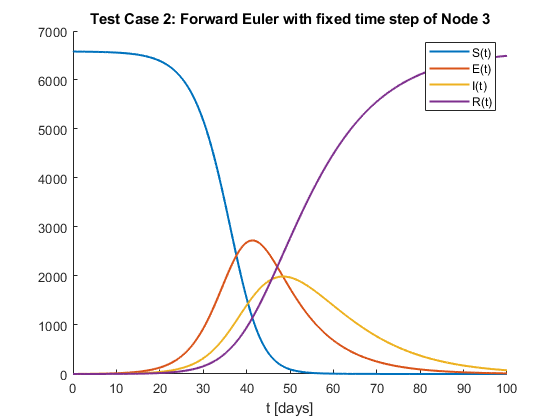

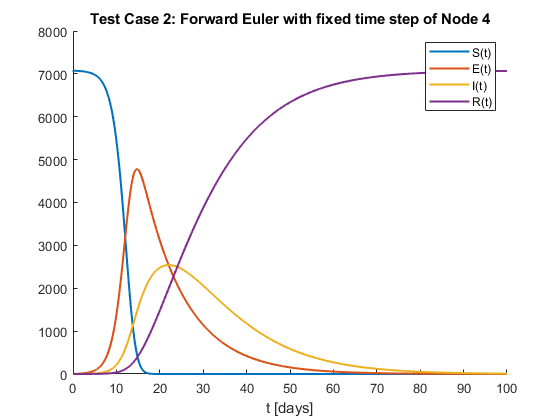

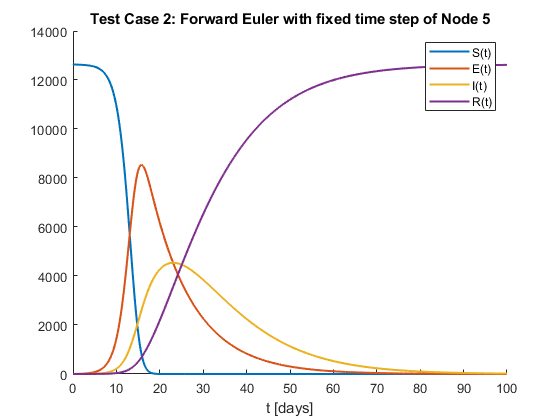

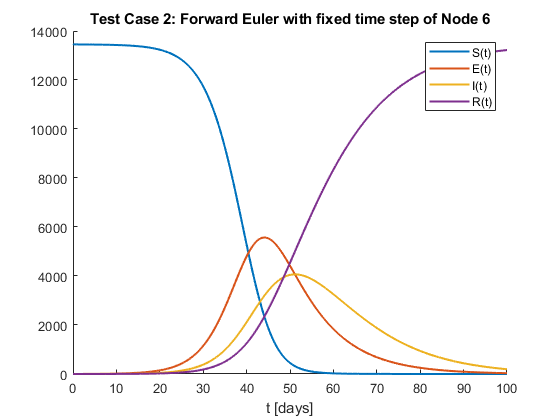

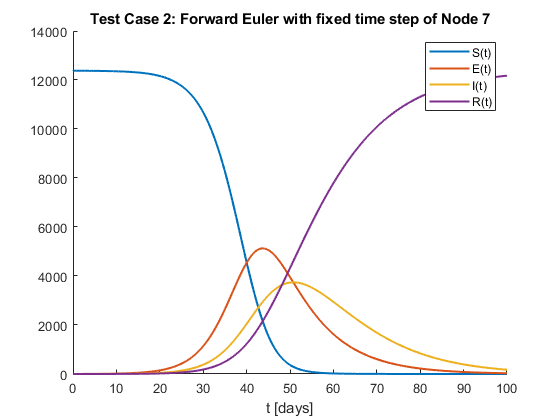

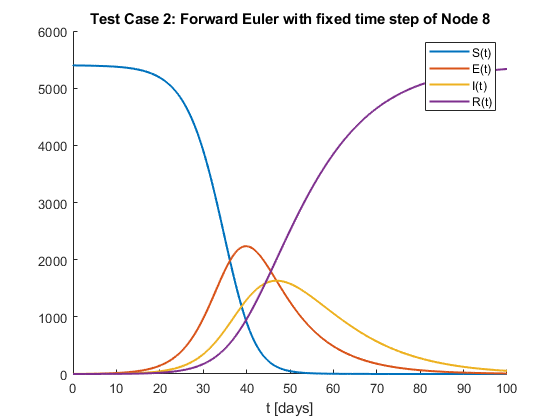

clc; clear; close all;

rng(5);

t_start = 0;
t_stop = 100;
timestep = 0.05;

%select input evaluation function
eval_u = 'GenInputVec';

%select model evaluation function
eval_f = 'EVALF';

[P, x_start, p, u] = initializeCambridgeCommunities();

% test FE function
tic;
[X] = forwardEulerFlipTheta(P, eval_f, x_start, p, eval_u, t_start, t_stop, timestep);
feFlipThetaElapsedTime = toc;

%% Convert SEIR cell time series to matrix
for i = 1:size(X,2)
    
    feFlipThetaState(:,i) = convertSeirCellToMat(X(:,i));
    
end

% Plot SEIR curves for each node
for i = 1:size(X,1)
    State = X(i,:);
    state = [State{1:end}];
    N(i,:) = sum(state, 1);
    figure(i);
    hold on;
    days = linspace(t_start,t_stop,length(state(1,1:end)));
    plot(days, state(1,1:end),  'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, state(2,1:end),  'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, state(3,1:end), 'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, state(4,1:end), 'LineWidth', 1.5);
    xlabel('t [days]');
    hold off;
    legend('S(t)','E(t)','I(t)','R(t)');
    title(['Test Case 2: Forward Euler with fixed time step of' ' Node ', num2str(i)])
    
    if i == 1
        sumState = state;     
    else
        sumState = sumState + state;     
    end
    
end

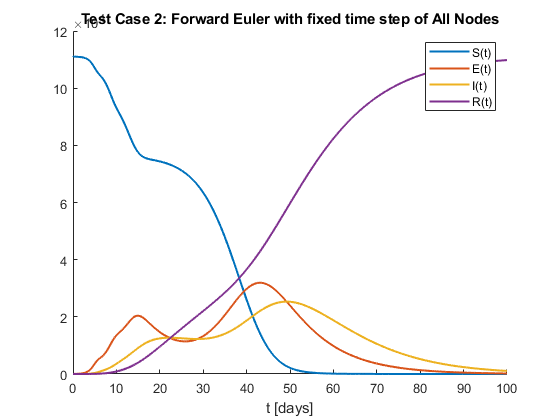


figure;
hold on;
days = linspace(t_start,t_stop,length(sumState(1,1:end)));
plot(days, sumState(1,1:end),  'LineWidth', 1.5);
xlabel('t [days]');

plot(days, sumState(2,1:end),  'LineWidth', 1.5);
xlabel('t [days]');

plot(days, sumState(3,1:end), 'LineWidth', 1.5);
xlabel('t [days]');

plot(days, sumState(4,1:end), 'LineWidth', 1.5);
xlabel('t [days]');
hold off;
legend('S(t)','E(t)','I(t)','R(t)');
title('Test Case 2: Forward Euler with fixed time step of All Nodes')

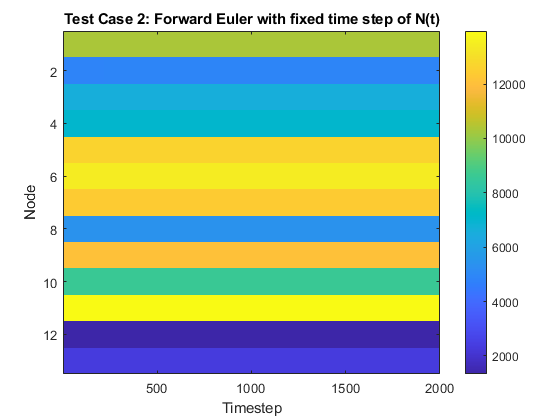


figure;
imagesc(N(:,:));
title('Test Case 2: Forward Euler with fixed time step of N(t)');
xlabel('Timestep');
ylabel('Node');
colorbar;


save('techChallengeFlipThetaStats.mat', 'feFlipThetaState', '-append');
save('techChallengeFlipThetaStats.mat', 'feFlipThetaElapsedTime', '-append');

#### Error Plot between Test Case 1 and 2  (Flip Theta)

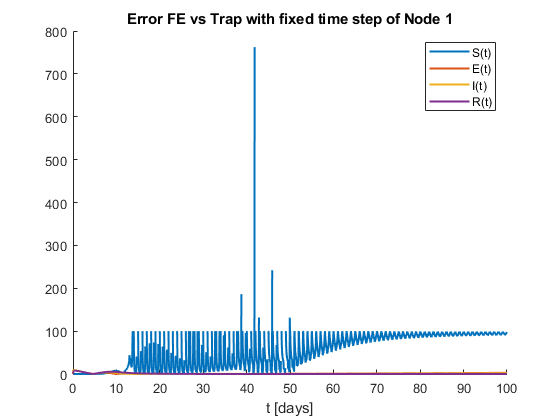

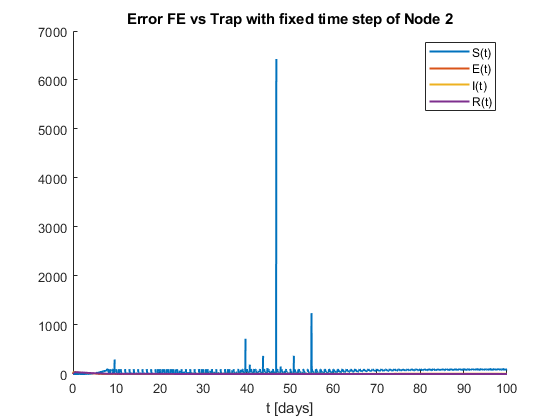

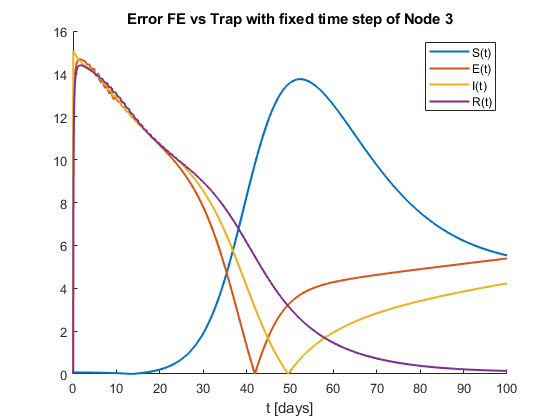

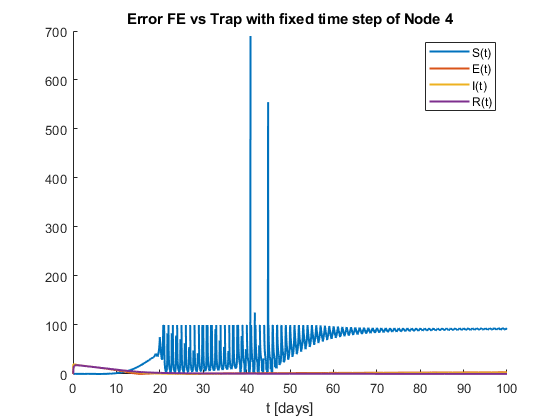

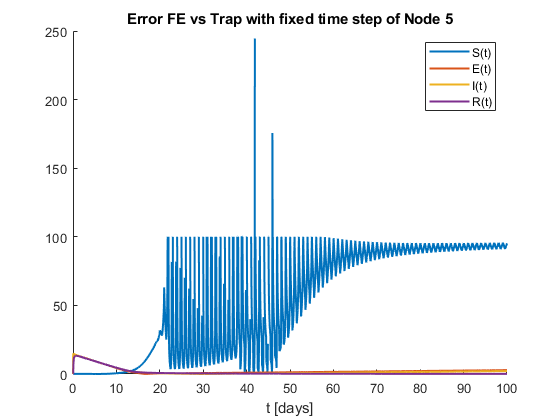

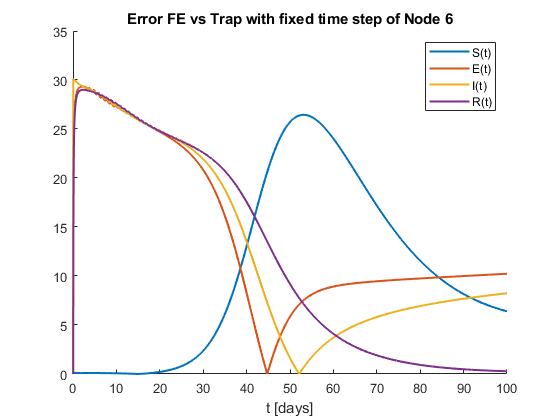

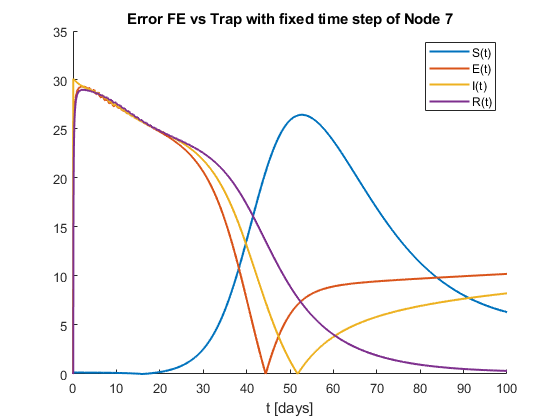

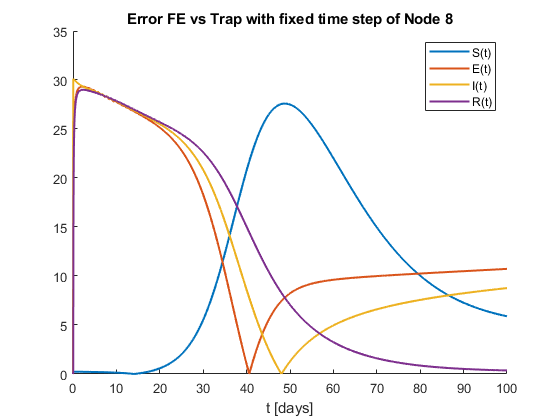

clc; clear; close all;

load('techChallengeFlipThetaStats.mat');

P = 13;
c = zeros(4, P*4);

for i=1:P
    
    c(1, (i-1)*4 + 1) = 1;
    c(2, (i-1)*4 + 2) = 1;
    c(3, (i-1)*4 + 3) = 1;
    c(4, (i-1)*4 + 4) = 1;
    
end

t_start = 0;
t_stop = 100;
rng(5);

% Calculate |feFlipThetaState - trapFlipThetaState|/|trapFlipThetaState|*100%
errorState = abs(feFlipThetaState - trapFlipThetaState)./trapFlipThetaState*100;

% Assign 0% for the initial stage to avoid NaN from division by 0
errorState(:,1) = zeros(52, 1);

%Sum Error
sumFeFlipThetaState = c * feFlipThetaState;
sumTrapFlipThetaState = c * trapFlipThetaState;
sumErrorState = abs(sumFeFlipThetaState - sumTrapFlipThetaState)./sumTrapFlipThetaState*100;

%% Convert SEIR matrix time series to cell
for i = 1:size(errorState,2)
    errorStateCell(:,i) = convertSeirMatToCell(errorState(:,i));
end

% Plot SEIR error curves for each node
for i = 1:size(errorStateCell,1)
    State = errorStateCell(i,:);
    state = [State{1:end}];
    N(i,:) = sum(state, 1);
    
    figure(i);
    hold on;
    days = linspace(t_start,t_stop,length(state(1,1:end)));
    plot(days, state(1,1:end),  'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, state(2,1:end),  'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, state(3,1:end), 'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, state(4,1:end), 'LineWidth', 1.5);
    xlabel('t [days]');
    hold off;
    
    legend('S(t)','E(t)','I(t)','R(t)');
    title(['Error FE vs Trap with fixed time step of' ' Node ', num2str(i)])
    
end

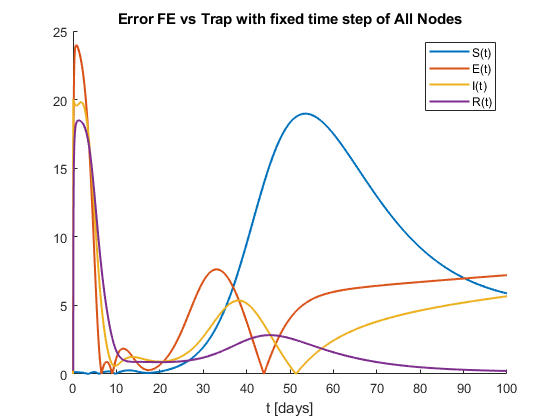



figure;
hold on;
days = linspace(t_start,t_stop,length(sumErrorState(1,1:end)));
plot(days, sumErrorState(1,1:end),  'LineWidth', 1.5);
xlabel('t [days]');

plot(days, sumErrorState(2,1:end),  'LineWidth', 1.5);
xlabel('t [days]');

plot(days, sumErrorState(3,1:end), 'LineWidth', 1.5);
xlabel('t [days]');

plot(days, sumErrorState(4,1:end), 'LineWidth', 1.5);
xlabel('t [days]');
hold off;
legend('S(t)','E(t)','I(t)','R(t)');
title('Error FE vs Trap with fixed time step of All Nodes')

#### Test Case 3: 13 Cambridge Communities - Adaptive Trapezoidal (Flip Theta)

clc; clear; close all;

t_start = 0;
t_stop = 100;
timestep = 0.1;
rng(5);

[P, x_start, p, u] = initializeCambridgeCommunities();

% test FE function
tic;
[X, trapFlipThetaAdaptiveT, trapFlipThetaAdaptiveNewtonLastIter] = trapezoidalFlipThetaAdaptive(P, x_start, p, u, t_stop, timestep); %t_start is always 0

At time t = 0
At time t = 1
At time t = 2
At time t = 3
At time t = 4
At time t = 5
At time t = 6
At time t = 7
At time t = 8
At time t = 9
At time t = 10
here
At time t = 11
At time t = 12
At time t = 13
At time t = 14
At time t = 15
At time t = 16
At time t = 17
At time t = 18
At time t = 19
At time t = 20
At time t = 21
At time t = 22
At time t = 23
At time t = 24
At time t = 25
At time t = 26
At time t = 27
At time t = 28
At time t = 29
At time t = 30
At time t = 31
At time t = 32
At time t = 33
At time t = 34
At time t = 35
At time t = 36
At time t = 37
At time t = 38
At time t = 39
At time t = 40
At time t = 41
At time t = 42
At time t = 43
At time t = 44
At time t = 45
At time t = 46
At time t = 47
At time t = 48
At time t = 49
At time t = 50
At time t = 51
At time t = 52
At time t = 53
At time t = 54
At time t = 55
At time t = 56
At time t = 57
At time t = 58
At time t = 59
At time t = 60
At time t = 61
At time t = 62
At time t = 63
At time t = 64
At time t = 65
At time t = 66


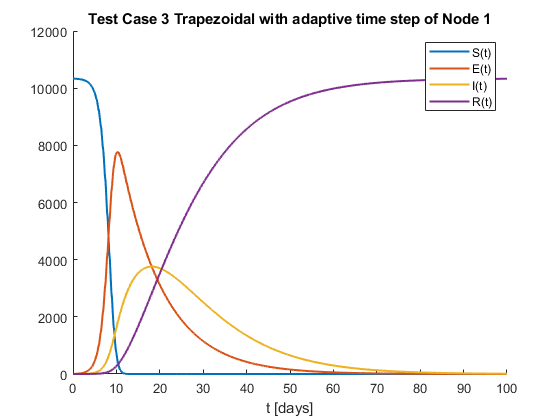

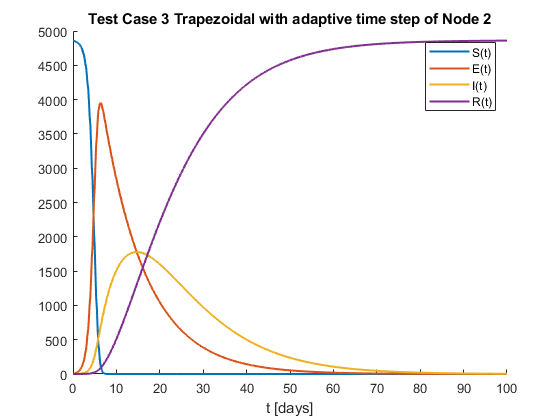

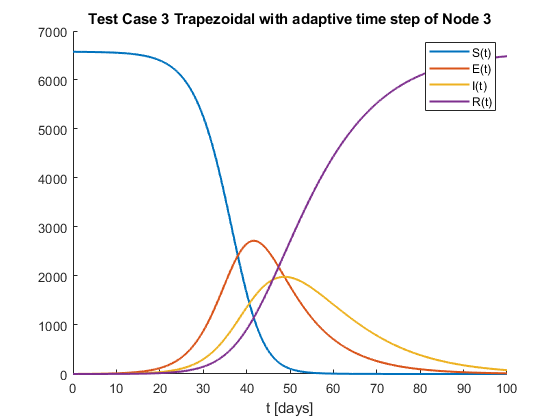

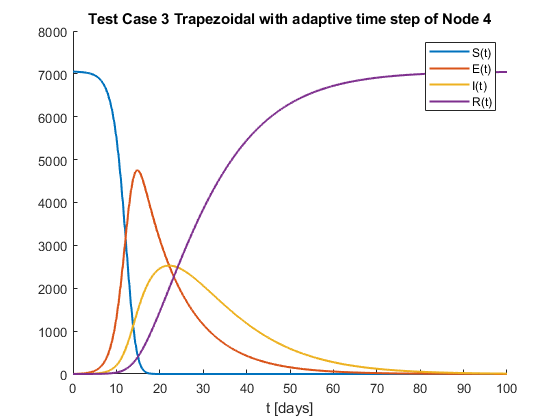

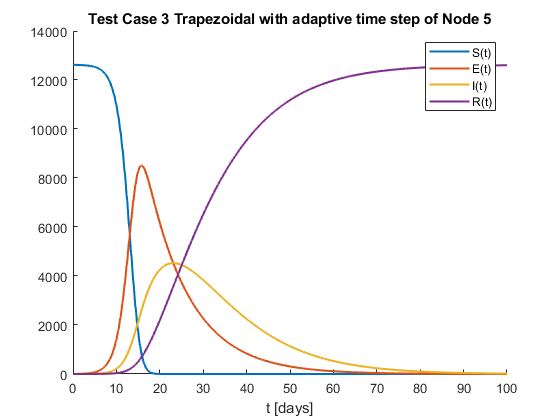

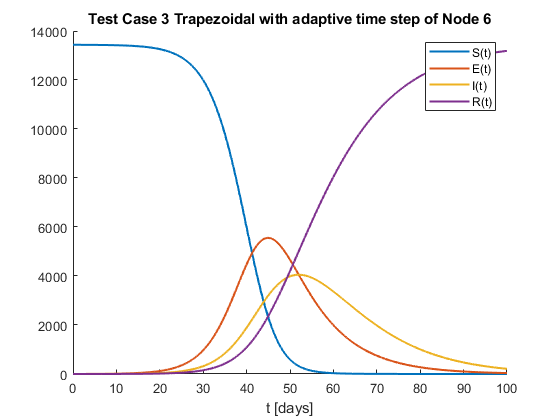

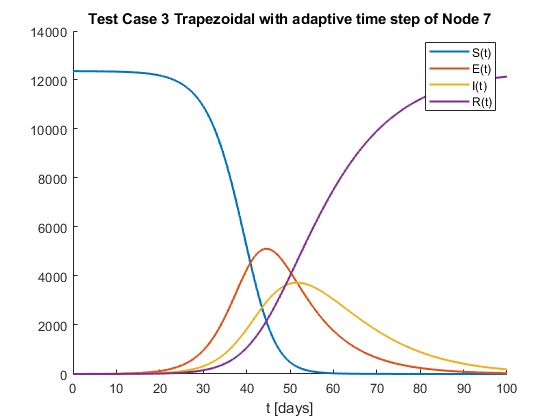

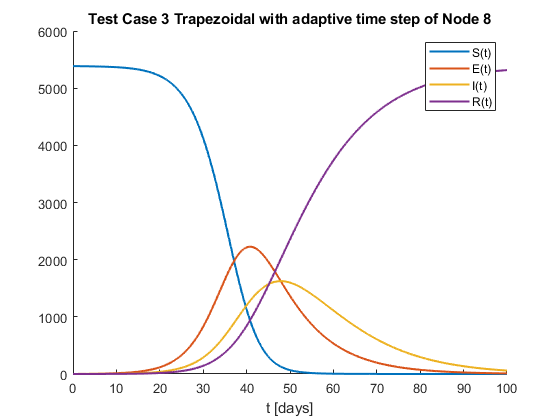

trapFlipThetaAdaptiveElapsedTime = toc;

%% Convert SEIR cell time series to matrix
for i = 1:size(X,2)
    trapFlipThetaAdaptiveState(:,i) = convertSeirCellToMat(X(:,i));
end

%% Plot SEIR curves for each node
for i = 1:size(X,1)
    
    State = X(i,:);
    state = [State{1:end}];
    
    N(i,:) = sum(state, 1);
    
    figure(i);
    hold on;
    days = linspace(t_start,t_stop,length(state(1,1:end)));
    plot(days, state(1,1:end),  'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, state(2,1:end),  'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, state(3,1:end), 'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, state(4,1:end), 'LineWidth', 1.5);
    xlabel('t [days]');
    hold off;
    legend('S(t)','E(t)','I(t)','R(t)');
    title(['Test Case 3 Trapezoidal with adaptive time step of' ' Node ', num2str(i)])
    
    if i == 1
        sumState = state;     
    else
        sumState = sumState + state;     
    end
end

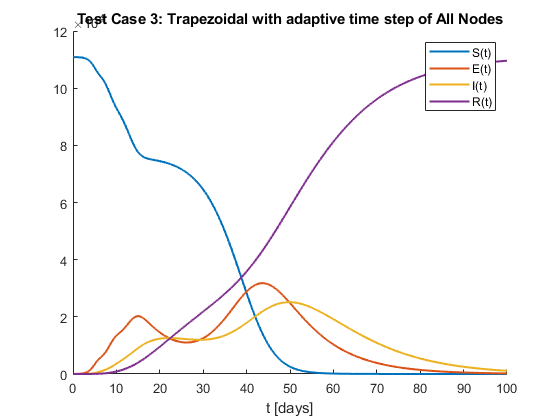


figure;
hold on;
days = linspace(t_start,t_stop,length(sumState(1,1:end)));
plot(days, sumState(1,1:end),  'LineWidth', 1.5);
xlabel('t [days]');

plot(days, sumState(2,1:end),  'LineWidth', 1.5);
xlabel('t [days]');

plot(days, sumState(3,1:end), 'LineWidth', 1.5);
xlabel('t [days]');

plot(days, sumState(4,1:end), 'LineWidth', 1.5);
xlabel('t [days]');
hold off;
legend('S(t)','E(t)','I(t)','R(t)');
title('Test Case 3: Trapezoidal with adaptive time step of All Nodes')

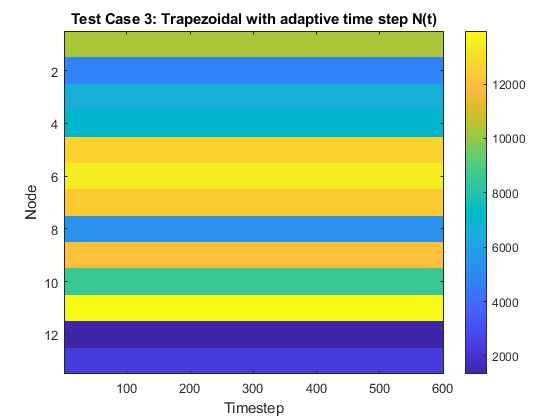


figure;
imagesc(N(:,:));
title('Test Case 3: Trapezoidal with adaptive time step N(t)');
xlabel('Timestep');
ylabel('Node');
colorbar;


save('techChallengeFlipThetaStats.mat', 'trapFlipThetaAdaptiveState', '-append');
save('techChallengeFlipThetaStats.mat', 'trapFlipThetaAdaptiveElapsedTime', '-append');
save('techChallengeFlipThetaStats.mat', 'trapFlipThetaAdaptiveT', '-append');
save('techChallengeFlipThetaStats.mat', 'trapFlipThetaAdaptiveNewtonLastIter', '-append');

#### Error Plot between Test Case 1 and 3 (Flip Theta)

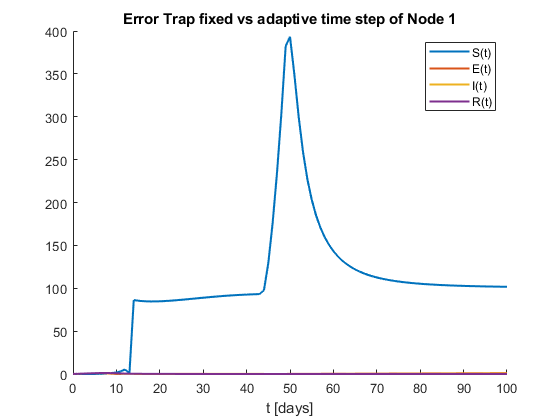

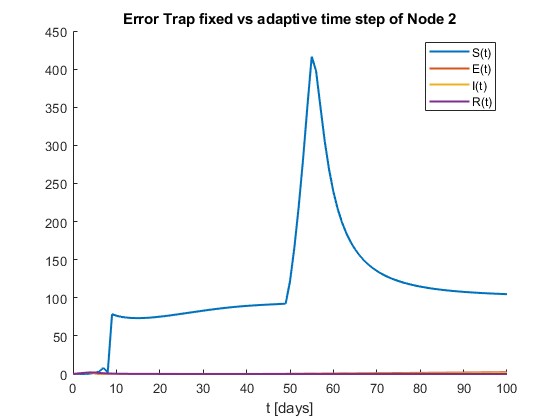

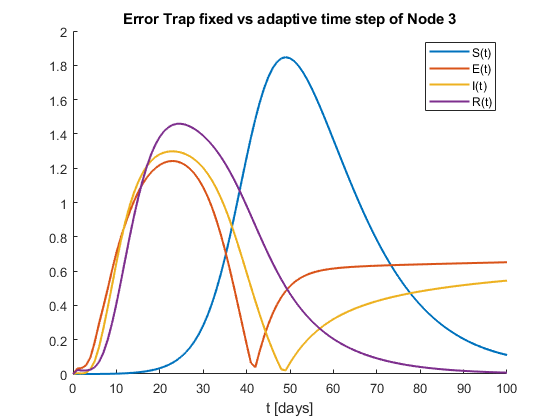

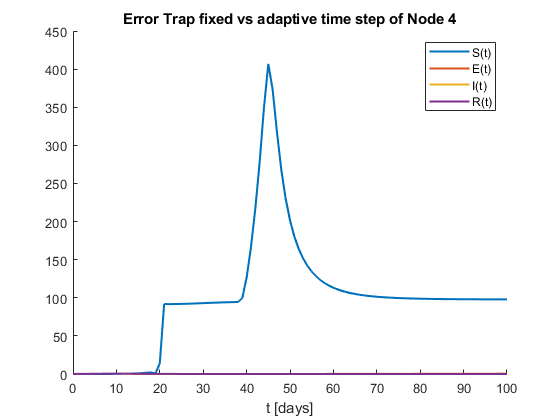

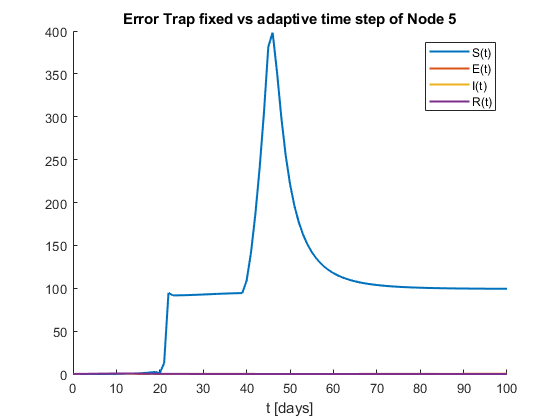

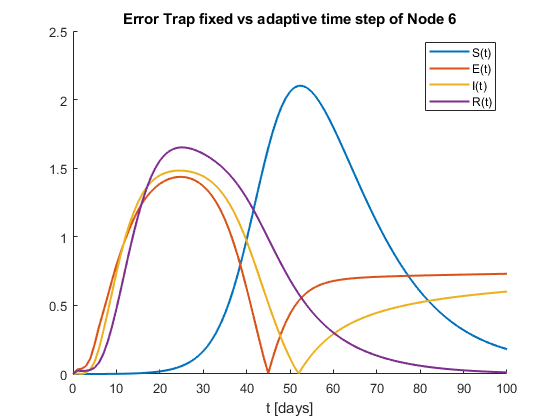

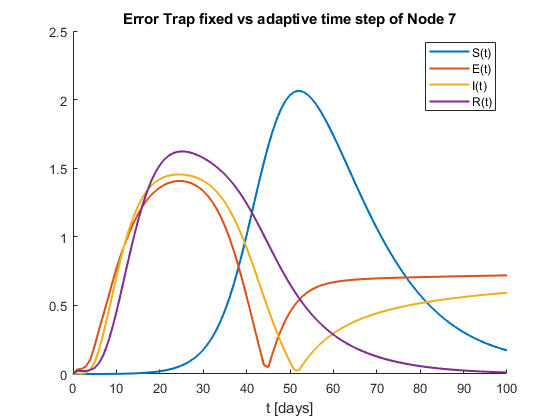

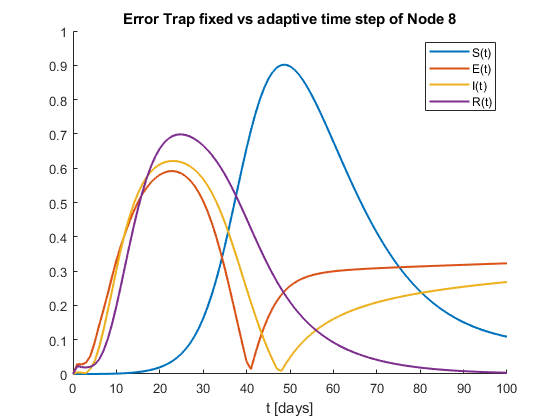

clc; clear; close all;

load('techChallengeFlipThetaStats.mat');

P = 13;
c = zeros(4, P*4);

for i=1:P
    
    c(1, (i-1)*4 + 1) = 1;
    c(2, (i-1)*4 + 2) = 1;
    c(3, (i-1)*4 + 3) = 1;
    c(4, (i-1)*4 + 4) = 1;
    
end

t_start = 0;
t_stop = 100;
rng(5);

%Get SEIR trapezoidal state at the end of each day
timestep = 0.05;
numTimeStepsPerDay = 1/timestep;

for i=1:100
    trapFlipThetaDayState(:, i) = trapFlipThetaState(:, i*numTimeStepsPerDay+1);
end
trapFlipThetaDayState = [trapFlipThetaState(:,1) trapFlipThetaDayState];   %Add the initial state at t=0

%Get SEIR adaptive trapezoidal state at the end of each day
day = 1;
for i = 1:size(trapFlipThetaAdaptiveT, 2)
    
    %It's the time at the end of the day (i.e. is integer)
    if (floor(trapFlipThetaAdaptiveT(i)) == ceil(trapFlipThetaAdaptiveT(i)))
        trapFlipThetaAdaptiveDayState(:, day) = trapFlipThetaAdaptiveState(:, i);
        day = day+1;
    end
end


% Calculate error in percentage
errorState = abs(trapFlipThetaAdaptiveDayState - trapFlipThetaDayState)./trapFlipThetaDayState*100;

% Assign 0% for the initial stage to avoid NaN from division by 0
errorState(:,1) = zeros(52, 1);

%Sum Day Error
sumTrapFlipThetaDayState = c * trapFlipThetaDayState;
sumTrapFlipThetaAdaptiveDayState = c * trapFlipThetaAdaptiveDayState;
sumErrorState = abs(sumTrapFlipThetaAdaptiveDayState - sumTrapFlipThetaDayState)./sumTrapFlipThetaDayState*100;

%% Convert SEIR matrix time series to cell
for i = 1:size(errorState,2)
    errorStateCell(:,i) = convertSeirMatToCell(errorState(:,i));
end

% Plot SEIR error curves for each node
for i = 1:size(errorStateCell,1)
    State = errorStateCell(i,:);
    state = [State{1:end}];
    N(i,:) = sum(state, 1);
    
    figure(i);
    hold on;
    days = linspace(t_start,t_stop,length(state(1,1:end)));
    plot(days, state(1,1:end),  'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, state(2,1:end),  'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, state(3,1:end), 'LineWidth', 1.5);
    xlabel('t [days]');
    
    plot(days, state(4,1:end), 'LineWidth', 1.5);
    xlabel('t [days]');
    hold off;
    
    legend('S(t)','E(t)','I(t)','R(t)');
    title(['Error Trap fixed vs adaptive time step of' ' Node ', num2str(i)])
    
end

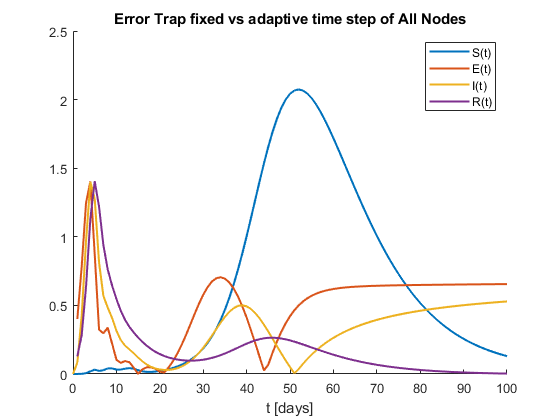



figure;
hold on;
days = linspace(t_start,t_stop,length(sumErrorState(1,1:end)));
plot(days, sumErrorState(1,1:end),  'LineWidth', 1.5);
xlabel('t [days]');

plot(days, sumErrorState(2,1:end),  'LineWidth', 1.5);
xlabel('t [days]');

plot(days, sumErrorState(3,1:end), 'LineWidth', 1.5);
xlabel('t [days]');

plot(days, sumErrorState(4,1:end), 'LineWidth', 1.5);
xlabel('t [days]');
hold off;
legend('S(t)','E(t)','I(t)','R(t)');
title('Error Trap fixed vs adaptive time step of All Nodes')